## Caso de estudio 1: ítem 2 

   En el archivo Curvas_Medidas_RLC_2025.xls (datos en la hoja 1 y etiquetas en la hoja  2) están las series de datos que sirven para deducir los valores de R, L y C del circuito. Emplear  el método de la respuesta al escalón, tomando como salida la tensión en el capacitor. 

clc; clear all; close all; 

%% Import data from spreadsheet
%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "Hoja1";
opts.DataRange = "A1:E20001";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Import the data
tbl = readtable("C:\Users\Maca\Documents\UNC\4toAÑO\1CUATRI\SC2\Folder Github TP´s\Control-System-II-TP-s\TP1\documentation\Curvas_Medidas_RLC_2025.xls", opts, "UseExcel", false);

%% Convert to output type
t = tbl.VarName1;
I = tbl.VarName2;
V_c = tbl.VarName3;
V_in = tbl.VarName4;
V_o = tbl.VarName5;

%% Clear temporary variables
clear opts tbl

Ploteo de las gráficas:

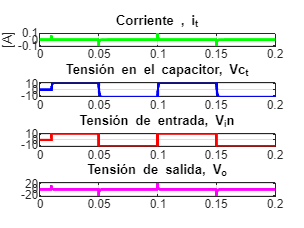

figure; % Creación de la figura sin especificar un número, MATLAB asignará automáticamente
hold on

% Primera subgráfica - Tensión de entrada
subplot(4,1,1);
plot(t, I, 'g', 'LineWidth', 2);
title('Corriente , i_t');
grid on;

% Segunda subgráfica - Tensión en el capacitor
subplot(4,1,2);
plot(t, V_c, 'b', 'LineWidth', 2);
title('Tensión en el capacitor, Vc_t');
grid on;

% Tercera subgráfica - Corriente
subplot(4,1,3);
plot(t, V_in, 'r', 'LineWidth', 2);
title('Tensión de entrada, V_in'); % Corrigiendo el título, antes decía "Corriente"
grid on;

% Cuarta subgráfica - Tensión de salida
subplot(4,1,4);
plot(t, V_o, 'm', 'LineWidth', 2);
title('Tensión de salida, V_o'); % Evitando duplicación incorrecta del título "Corriente"
grid on;

subplot(4,1,1)
ylabel("[A]")

Para encontrar la Función de transferencia se aplica "El artículo de Chen" con sus respectivas fórmulas 

% Para encontrar la Función de transferencia se aplica "El artículo de Chen" 
% con sus respectivas fórmulas 

% Apply The Second-Order Systems with differents poles method 

% y(t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(t1/T1))- (((T3-T2)/(T1-T2))*exp(-t1/T2)));
% y(2*t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(2*t1/T1))- (((T3-T2)/(T1-T2))*exp(-(2*t1)/T2)));
% y(3*t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(3*t1/T1))- (((T3-T2)/(T1-T2))*exp(-(3*t1)/T2)));

% Obtain maximium value from t (RLC circuit measure).
max_t= max(t);

% Define el valor de entrada para normalizar.
A= 12;

% Time array.
t0= t;
%Vc array.
y=V_c;

% Chen Method application
% Take three point to apply Chen Method.
% First point time.

i= 1020;
t_inic= t0(i);
% Define step.
h=20;
% Obtain y1.
t_t1= t0(i) %0.0105

t_t1 = 0.0102

y_t1= y(i)/A

y_t1 = 0.3227

% Obtain y2.
t_2t1= t0(i+h)

t_2t1 = 0.0104

y_2t1= y(i+h)/A

y_2t1 = 0.5529

% Obtain y3.
t_3t1= t0(i+(2*h))

t_3t1 = 0.0106

y_3t1= y(i+(2*h))/A

y_3t1 = 0.7048


% Normalizo la ganancia 
% Add abs(y(end)), because 'end' take value= -12V (Alternate input signal).
K= abs(y(end))/A;

% Calculating k1, k2, k3.
k1= ((y_t1)/K)-1;
k2= ((y_2t1)/K)-1;
k3= ((y_3t1)/K)-1;

% Calculating b, alfa1, alfa2.
b= 4*(k1^(3))*k3- 3*(k1^2)*(k2^2)- 4*(k2^3)+ (k3^2)+ 6*k1*k2*k3;
alfa1= (k1*k2+ k3- sqrt(b))/(2*((k1^2)+ k2));
alfa2= (k1*k2+ k3+ sqrt(b))/(2*((k1^2)+ k2));

% Calculating Beta.
% beta= (2*(k1^3)+ 3*k1*k2+ k3- sqrt(b))/(sqrt(b));
% Alternative
beta= (k1+alfa2)/(alfa1-alfa2);

% Calculating the estimates of the time constants T1, T2 and T3
desp=0.01 %Desplazamiento en el tiempo para que arranque = a Y

desp = 0.0100

% observado en la gráfica 
% se resta por mov a derecha
T1= -(t_t1 - desp)/(log(alfa1))

T1 = 7.2437e-06

T2= -(t_t1 - desp)/(log(alfa2))

T2 = 4.5758e-04

T3= beta*(T1 - T2)+ T1

T3 = -4.3936e-06


% Build Transfer Function
s= tf('s');
sys= (K*(T3*s+1))/((T1*s+1)*(T2*s+1)); %%sin retardo
sys1= exp(-s*t_t1)*sys


sys1 =
 
                          -4.394e-06 s + 1
  exp(-0.0102*s) * -------------------------------
                   3.315e-09 s^2 + 0.0004648 s + 1
 
Continuous-time transfer function.
Model Properties


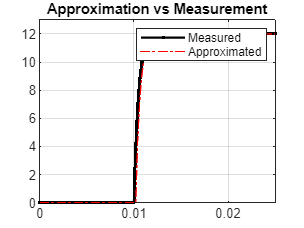

% [num, den]= tfdata(sys, 'v');

% Plot approximated step response
% Obtain step response with delay.
% [ys, ts]= step(sys*exp(-s*0.01), 'r-', 0.16);
figure(2)
[ys, ts]= step(A*sys1, 'r-', 0.5);   %aproximada
plot(t, V_c, 'k.-','LineWidth',1.5); %medida 
hold on;
plot(ts, ys, 'r-.');%aproximada
xlim([0, 0.025]);
ylim([0, 13]);
legend('Measured', 'Approximated');
title('Approximation vs Measurement');
grid on;

Ahora  con la FT de Chen y la FT de RLC  analítica encontrar L ,R,C   pero tendriamos 2 ec con 2 incgn entonces calcular C como : (agregar formulas 

%Cálculo de capacitor 
x1=1126

x1 = 1126

x2=x1+1

x2 = 1127

Cx1 = V_c(x1,1)

Cx1 = 11.1001

Cx2 = V_c(x2,1)

Cx2 = 11.1186

tx1 = t(x1,1)

tx1 = 0.0113

tx2 = t(x2,1)

tx2 = 0.0113

dVc = (Cx2-Cx1)/(tx2-tx1)

dVc = 1.8490e+03

ix1 = I(x1,1)

ix1 = 0.0041

Cap=ix1/dVc  % Cap=2.22[uF]

Cap = 2.2227e-06


%Cálculo de L y R 
 %sujeto a modificar para que se despeje solo de las ft 
sys %FT dado por el Articulo de Chen


sys =
 
         -4.394e-06 s + 1
  -------------------------------
  3.315e-09 s^2 + 0.0004648 s + 1
 
Continuous-time transfer function.
Model Properties


%FT analitica de RLC normalizada 

% FT = ((1/L*Cap)/(s^2+s*(R/L)+(1/L*C))

[num,dem] = tfdata((sys),'v')

num =          0   -0.0000    1.0000


dem =     0.0000    0.0005    1.0000


%igualó numerador de sys y FT analitica y luego cada termino del
%denominador para encontrar R y L 

L= dem(1,1)/Cap

L = 0.0015

R=dem(1,2)/Cap

R = 209.1285



% Puedes también comparar los polos:
polos_estimados = pole(sys);
polos_calculados = roots([L*Cap R*Cap 1]); % Polos de LC*s^2 + RC*s + 1 = 0
fprintf('Polos estimados (Chen): %f, %f\n', polos_estimados(1), polos_estimados(2));

Polos estimados (Chen): -138051.393789, -2185.395049


fprintf('Polos calculados (RLC): %f, %f\n', polos_calculados(1), polos_calculados(2));

Polos calculados (RLC): -138051.393789, -2185.395049


% Deberían ser similares si todo es consistente.





## Caso de estudio 1: ítem 3

   Una vez determinados los parámetros R, L y C, emplear la serie de corriente desde  0.05seg en adelante para validar el resultado superponiendo las gráficas.

% --- Punto 3: Validación usando la corriente ---

%FT= i(t)/Vin
% 1. Definir la FT para la corriente I(s)/Vin(s)
num_I = [Cap 0];            % Numerador: C*s + 0
den_I = [L*Cap R *Cap 1]; % Denominador: L*C*s^2 + R*C*s + 1
sys_I = tf(num_I, den_I);   % Crear el objeto de función de transferencia

% Mostrar la FT de corriente (opcional)
fprintf('\nFunción de Transferencia para Corriente I(s)/Vin(s):\n');


Función de Transferencia para Corriente I(s)/Vin(s):


disp(sys_I);

  tf with properties:

       Numerator: {[0 2.2227e-06 0]}
     Denominator: {[3.3146e-09 4.6483e-04 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



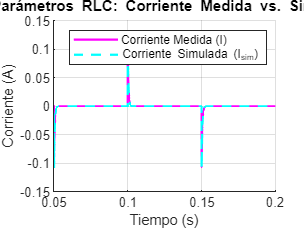


% 2. Simular la respuesta de corriente usando la V_in medida como entrada
% Usamos lsim(sistema, entrada, tiempo) 
%"lsim" ES LO MISMO QUE APLICAR  EULER -> EL FOR DE PUNTO 1 

[I_sim, t_sim] = lsim(sys_I, V_in, t); 
% t_sim será igual a t en este caso

% 3. Graficar y comparar
figure; % Crear una nueva figura
hold on; % Mantener los plots en la misma figura

% Graficar la corriente medida
plot(t, I, 'm-', 'LineWidth', 1.5, 'DisplayName', 'Corriente Medida (I)');

% Graficar la corriente simulada
plot(t_sim, I_sim, 'c--', 'LineWidth', 1.5, 'DisplayName', 'Corriente Simulada (I_{sim})');

% 4. Ajustar la vista al rango solicitado y añadir detalles
xlim([0.05, max(t)]); % <-- Enfocar en t >= 0.05 segundos
xlabel('Tiempo (s)');
ylabel('Corriente (A)');
title('Validación de Parámetros RLC: Corriente Medida vs. Simulada (t \geq 0.05s)');
legend('show');
grid on;
hold off;


% --- Fin Punto 3 ---